clear;clc;close all;
tempo = 0;
degrau = 0;
resposta1 = 0;
resposta2 = 0;
resposta3 = 0;
resposta4 = 0;
resposta5 = 0;
resposta6 = 0;

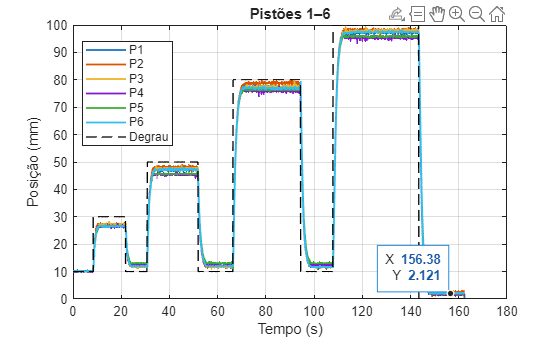

figure(1); clf
t = tempo;                  % use o seu vetor de tempo comum
Y = [resposta1, resposta2, resposta3, resposta4, resposta5, resposta6];  % Nx6
plot(t, Y, 'LineWidth', 1.4); grid on; hold on
plot(t, degrau, 'k--', 'LineWidth', 1)   % degrau de referência
title('Pistões 1–6')
xlabel('Tempo (s)'); ylabel('Posição (mm)')
legend({'P1','P2','P3','P4','P5','P6','Degrau'}, 'Location','best')
hold off

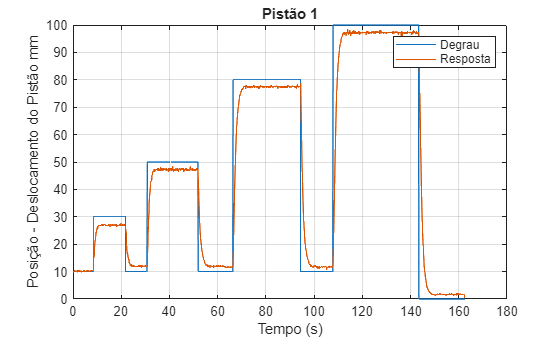

figure(2)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta1), hold off;
title('Pistão 1');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

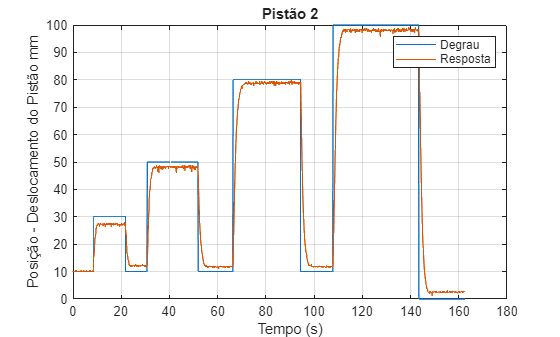


figure(3)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta2), hold off;
title('Pistão 2');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

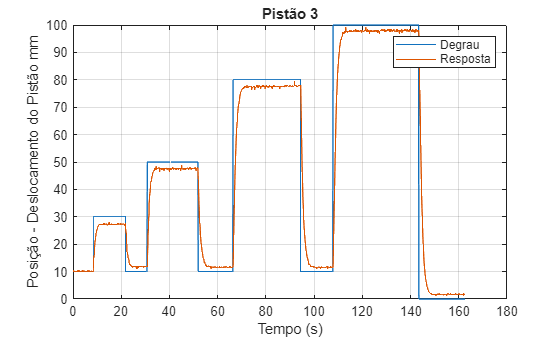


figure(4)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta3), hold off;
title('Pistão 3');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

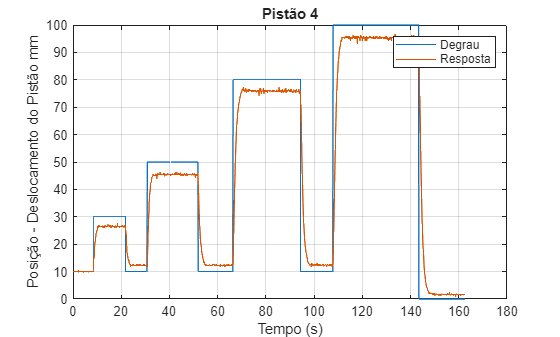


figure(5)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta4), hold off;
title('Pistão 4');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

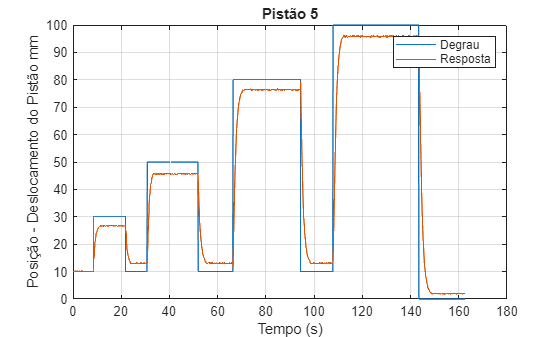


figure(6)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta5), hold off;
title('Pistão 5');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

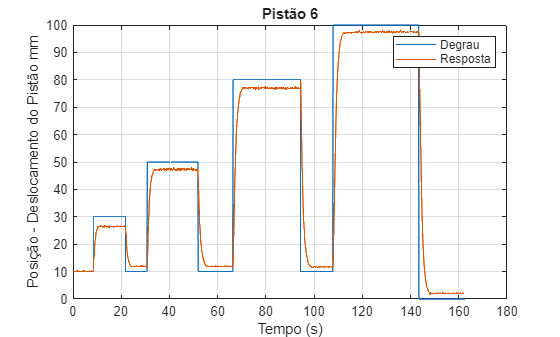


figure(7)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta6), hold off;
title('Pistão 6');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão mm');
legend('Degrau', 'Resposta');

%----Ziegler-Nichols (1ª Ordem Aproximada)----
%----Valores dos Gráficos----%

% Pistão 1
ui_1 = 10;
uf_1 = 30;
yi_1 = 10;
yf_1 = 27.08;
ti_i = 8.38;
t_tau1_abs = 8.82;   % instante em que atinge 63,2%
Kp = 5;              % ganho proporcional do ensaio

% Diferenças
dy1 = yf_1 - yi_1;
du1 = uf_1 - ui_1;

% Ganho da malha fechada
K1 = dy1 / du1;

% Constante de tempo (63,2%)
tau1 = t_tau1_abs - ti_i;

% Função de transferência da malha FECHADA (1ª ordem)
T1 = tf(K1, [tau1 1]);

% Função de transferência da planta (1ª ordem) em malha ABERTA
G1 = minreal( T1 / (Kp * (1 - T1)) );

% Exibição
disp('Função de transferência do Pistão 1:')
G1

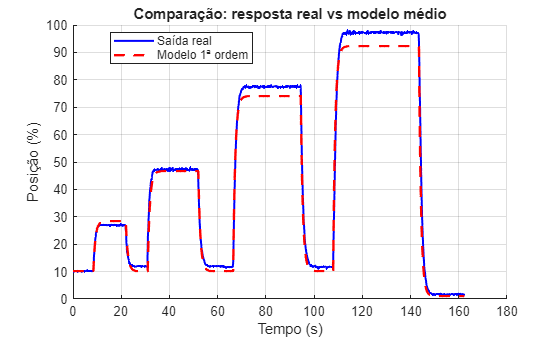

% ==== ENTRADAS (preencha com seus 4 ensaios) ====
Kp = 5;  % Kp usado em cada ensaio (ou um único valor se igual)

ui = [10 10 10 10];   % entrada inicial de cada ensaio
uf = [30 50 80 100];   % entrada final
yi = [10 11.95 11.67 11.79];   % saída inicial
yf = [27.08 47.36 77.47 97.1];  % saída final (cada ensaio)
t_i       = [8.38  30.642  66.268  107.74];  % instante do degrau (s)
t_tau_abs = [8.82  31.3  67.3  109.120];  % tempo (absoluto) em que atingiu 63,2%

% ==== CÁLCULO POR ENSAIO (malha fechada) ====
du = uf - ui;
dy = yf - yi;

K_T = dy ./ du;                       % ganho da malha fechada T(s)
tau_T = t_tau_abs - t_i;              % constante de tempo da malha fechada

% (Opcional) descarte ensaios inválidos:
valid = isfinite(K_T) & isfinite(tau_T) & tau_T>0 & du~=0;

K_Tv   = K_T(valid);
tau_Tv = tau_T(valid);

% ==== MÉDIAS ROBUSTAS ====
K_T_med   = median(K_Tv);             % média robusta do ganho de T
tau_T_med = median(tau_Tv);           % média robusta do tau de T

% ==== FT MÉDIA EM MALHA FECHADA ====

% === 1) Modelo médio já calculado ===

% K_T_med, tau_T_med, Kp (escalar)
T_avg = tf(K_T_med, [tau_T_med 1]);
G_avg = minreal( T_avg / (Kp * (1 - T_avg)) );

% === 2) Malha fechada do modelo médio ===
T_sim = feedback(Kp * G_avg, 1);

% === 3) Dados reais (um ensaio) ===
t = tempo(:);          % tempo do ensaio real
u = degrau(:);         % entrada aplicada (degrau real)
y = resposta1(:);       % saída medida

% --- garantir tempo estritamente crescente e sem duplicados
[t, ia] = unique(t, 'stable');
u = u(ia); y = y(ia);

% --- 3.1) Reamostrar para passo uniforme (recomendado p/ sua versão)
dt = diff(t);
Ts = median(dt(~isnan(dt) & isfinite(dt)));  % passo típico
t_uni = (t(1):Ts:t(end)).';                  % grade uniforme

% Reamostra: degrau como "previous" (degrau real), saída linear
u_uni = interp1(t, u, t_uni, 'previous', 'extrap');
y_uni = interp1(t, y, t_uni, 'linear',   'extrap');

% === 4) Simulação com compensação de nível inicial ===
% Para não gerar "transiente" antes do degrau, simule a variação
u0 = u_uni(1);
y0 = y_uni(1);
y_model = lsim(T_sim, u_uni - u0, t_uni) + y0;

% === 5) Plots de comparação ===
figure; grid on; hold on
plot(t_uni, y_uni, 'b', 'LineWidth', 1.5)
plot(t_uni, y_model, '--r', 'LineWidth', 1.8)
xlabel('Tempo (s)'); ylabel('Posição (%)')
legend('Saída real', 'Modelo 1ª ordem', 'Location','best')
title('Comparação: resposta real vs modelo médio')

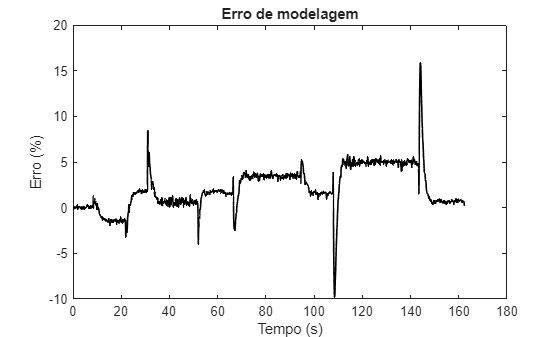


figure; grid on
plot(t_uni, y_uni - y_model, 'k', 'LineWidth', 1.2)
xlabel('Tempo (s)'); ylabel('Erro (%)')
title('Erro de modelagem')


% === 6) Métrica de ajuste ===
fit = 100 * (1 - norm(y_uni - y_model) / norm(y_uni - mean(y_uni)));
fprintf('Ajuste do modelo: %.2f %%\n', fit);

Ajuste do modelo: 90.92 %


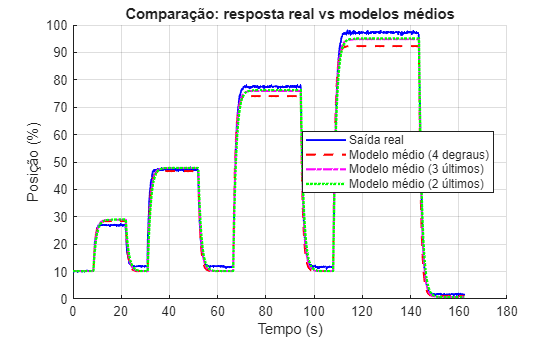

%% ==== ENTRADAS (4 ensaios) ====
Kp = 5;  % ganho proporcional usado nos ensaios

ui = [10 10 10 10];              % entrada inicial
uf = [30 50 80 100];             % entrada final
yi = [10 11.95 11.67 11.79];     % saída inicial
yf = [27.08 47.36 77.47 97.1];   % saída final
t_i       = [8.38  30.642  66.268  107.74];   % instante do degrau (s)
t_tau_abs = [8.82  31.3    67.3    109.120];  % tempo (abs) 63,2%

%% ==== CÁLCULO POR ENSAIO (malha fechada) ====
du   = uf - ui;
dy   = yf - yi;
K_T  = dy ./ du;                 % ganho da malha fechada T(s)
tau_T = t_tau_abs - t_i;         % constante de tempo da malha fechada

% Ensaios válidos
valid = isfinite(K_T) & isfinite(tau_T) & tau_T>0 & du~=0;
validIdx = find(valid);

%% ==== 1) MODELO MÉDIO (TODOS OS 4 DEGRAUS) ====
K_T_med_4   = median(K_T(validIdx));
tau_T_med_4 = median(tau_T(validIdx));

T_avg_4 = tf(K_T_med_4, [tau_T_med_4 1]);
G_avg_4 = minreal( T_avg_4 / (Kp * (1 - T_avg_4)) );
T_sim_4 = feedback(Kp * G_avg_4, 1);

%% ==== 2) MODELO MÉDIO (3 ÚLTIMOS DEGRAUS) ====
if numel(validIdx) >= 3
    last3 = validIdx(end-2:end);
    K_T_med_3   = median(K_T(last3));
    tau_T_med_3 = median(tau_T(last3));

    T_avg_3 = tf(K_T_med_3, [tau_T_med_3 1]);
    G_avg_3 = minreal( T_avg_3 / (Kp * (1 - T_avg_3)) );
    T_sim_3 = feedback(Kp * G_avg_3, 1);
else
    error('Menos de três ensaios válidos.');
end

%% ==== 3) MODELO MÉDIO (2 ÚLTIMOS DEGRAUS) ====
if numel(validIdx) >= 2
    last2 = validIdx(end-1:end);
    K_T_med_2   = median(K_T(last2));
    tau_T_med_2 = median(tau_T(last2));

    T_avg_2 = tf(K_T_med_2, [tau_T_med_2 1]);
    G_avg_2 = minreal( T_avg_2 / (Kp * (1 - T_avg_2)) );
    T_sim_2 = feedback(Kp * G_avg_2, 1);
else
    error('Menos de dois ensaios válidos.');
end

%% ==== DADOS REAIS PARA COMPARAÇÃO ====
% Troque conforme o ensaio real que deseja usar
t = tempo(:);
u = degrau(:);
y = resposta1(:);

% --- garantir tempo crescente e sem duplicados
[t, ia] = unique(t, 'stable');
u = u(ia); y = y(ia);

% --- Reamostragem uniforme
dt = diff(t);
Ts = median(dt(~isnan(dt) & isfinite(dt)));
t_uni = (t(1):Ts:t(end)).';

u_uni = interp1(t, u, t_uni, 'previous', 'extrap');
y_uni = interp1(t, y, t_uni, 'linear',   'extrap');

% --- Ajuste de níveis
u0 = u_uni(1);
y0 = y_uni(1);

%% ==== SIMULAÇÕES ====
y_model_4 = lsim(T_sim_4, u_uni - u0, t_uni) + y0;
y_model_3 = lsim(T_sim_3, u_uni - u0, t_uni) + y0;
y_model_2 = lsim(T_sim_2, u_uni - u0, t_uni) + y0;

%% ==== PLOTS DE COMPARAÇÃO ====
figure; grid on; hold on
plot(t_uni, y_uni, 'b', 'LineWidth', 1.4)
plot(t_uni, y_model_4, '--r', 'LineWidth', 1.6)
plot(t_uni, y_model_3, '-.m', 'LineWidth', 1.6)
plot(t_uni, y_model_2, ':g', 'LineWidth', 1.8)
xlabel('Tempo (s)'); ylabel('Posição (%)')
legend('Saída real', ...
       'Modelo médio (4 degraus)', ...
       'Modelo médio (3 últimos)', ...
       'Modelo médio (2 últimos)', ...
       'Location','best')
title('Comparação: resposta real vs modelos médios')

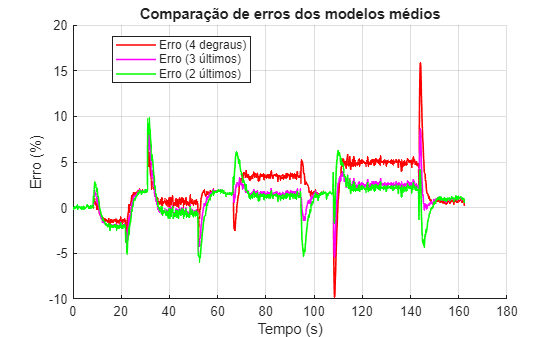


%% ==== PLOTS DE ERROS ====
figure; grid on; hold on
plot(t_uni, y_uni - y_model_4, 'r', 'LineWidth', 1.2)
plot(t_uni, y_uni - y_model_3, 'm', 'LineWidth', 1.2)
plot(t_uni, y_uni - y_model_2, 'g', 'LineWidth', 1.2)
xlabel('Tempo (s)'); ylabel('Erro (%)')
legend('Erro (4 degraus)', 'Erro (3 últimos)', 'Erro (2 últimos)', 'Location','best')
title('Comparação de erros dos modelos médios')


%% ==== MÉTRICAS DE AJUSTE (FIT) ====
fit_4 = 100 * (1 - norm(y_uni - y_model_4) / norm(y_uni - mean(y_uni)));
fit_3 = 100 * (1 - norm(y_uni - y_model_3) / norm(y_uni - mean(y_uni)));
fit_2 = 100 * (1 - norm(y_uni - y_model_2) / norm(y_uni - mean(y_uni)));

fprintf('\n===== MÉTRICAS DE AJUSTE =====\n');


===== MÉTRICAS DE AJUSTE =====


fprintf('Ajuste (4 degraus): %.2f %%\n', fit_4);

Ajuste (4 degraus): 90.92 %


fprintf('Ajuste (3 últimos): %.2f %%\n', fit_3);

Ajuste (3 últimos): 94.42 %


fprintf('Ajuste (2 últimos): %.2f %%\n', fit_2);

Ajuste (2 últimos): 93.73 %



%% ==== RESUMO DOS PARÂMETROS MÉDIOS ====
fprintf('\n--- Parâmetros médios (4 degraus) ---\n');


--- Parâmetros médios (4 degraus) ---


fprintf('K_T = %.5g | tau_T = %.5g s\n', K_T_med_4, tau_T_med_4);

K_T = 0.91262 | tau_T = 0.845 s



fprintf('\n--- Parâmetros médios (3 últimos) ---\n');


--- Parâmetros médios (3 últimos) ---


fprintf('K_T = %.5g | tau_T = %.5g s\n', K_T_med_3, tau_T_med_3);

K_T = 0.94 | tau_T = 1.032 s



fprintf('\n--- Parâmetros médios (2 últimos) ---\n');


--- Parâmetros médios (2 últimos) ---


fprintf('K_T = %.5g | tau_T = %.5g s\n', K_T_med_2, tau_T_med_2);

K_T = 0.94394 | tau_T = 1.206 s


%--------Pisão 1--------%
Kp = 5;

ui = [10;10;10;10]; uf = [30;50;80;100];
yi = [10;11.95;11.67;11.79]; yf = [27.08;47.36;77.47;97.1];
t_i = [8.38;30.642;66.268;107.74];
t_tau_abs = [8.82;31.3;67.3;109.120];
meas(1).tempo  = tempo(:);
meas(1).degrau = degrau(:);
meas(1).saida  = resposta1(:);
out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas);

% Acessando o modelo "last2"
T_last2 = out(1).models(strcmp({out(1).models.name},'last2')).T_avg


T_last2 =
 
    0.9439
  -----------
  1.206 s + 1
 
Continuous-time transfer function.


G_last2 = out(1).models(strcmp({out(1).models.name},'last2')).G_avg


G_last2 =
 
    0.1565
  -----------
  s + 0.04648
 
Continuous-time transfer function.


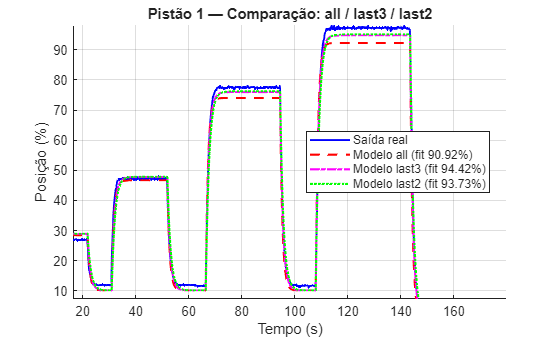

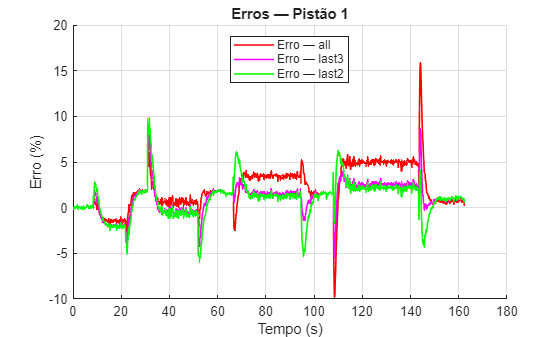

fits = show_fit_all_subsets(out, 1, 'Pistão 1');

disp(fits)   % ordem: [fit_all, fit_last3, fit_last2] (para os que existirem)

   90.9161
   94.4209
   93.7346



%--------Pisão 2--------%
Kp = 5;

ui = [10;10;10;10]; uf = [30;50;80;100];
yi = [10.16;12.12;11.74;11.62]; yf = [27.05;48.05;78.81;98.33];
t_i = [8.38;30.642;66.268;107.74];
t_tau_abs = [8.83;31.42;67.38;108.956];
meas(2).tempo  = tempo(:);
meas(2).degrau = degrau(:);
meas(2).saida  = resposta2(:);
out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas);

% Acessando o modelo "last2"
T_last2 = out(1).models(strcmp({out(1).models.name},'last2')).T_avg


T_last2 =
 
    0.9608
  -----------
  1.164 s + 1
 
Continuous-time transfer function.


G_last2 = out(1).models(strcmp({out(1).models.name},'last2')).G_avg


G_last2 =
 
    0.1651
  -----------
  s + 0.03368
 
Continuous-time transfer function.


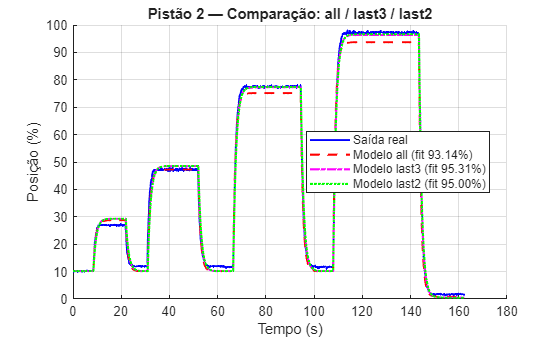

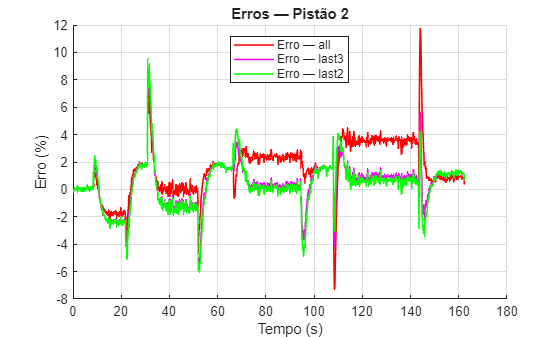

fits = show_fit_all_subsets(out, 1, 'Pistão 2');

disp(fits)   % ordem: [fit_all, fit_last3, fit_last2] (para os que existirem)

   93.1407
   95.3122
   95.0033



%--------Pisão 3--------%
Kp = 5;

ui = [10;10;10;10]; uf = [30;50;80;100];
yi = [10.01;11.84;11.57;11.6]; yf = [27.11;47.79;77.83;97.855];
t_i = [8.38;30.642;66.268;107.74];
t_tau_abs = [8.83;31.42;67.38;108.956];
meas(3).tempo  = tempo(:);
meas(3).degrau = degrau(:);
meas(3).saida  = resposta3(:);
out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas);

% Acessando o modelo "last2"
T_last2 = out(1).models(strcmp({out(1).models.name},'last2')).T_avg


T_last2 =
 
    0.9525
  -----------
  1.164 s + 1
 
Continuous-time transfer function.


G_last2 = out(1).models(strcmp({out(1).models.name},'last2')).G_avg


G_last2 =
 
    0.1637
  -----------
  s + 0.04082
 
Continuous-time transfer function.


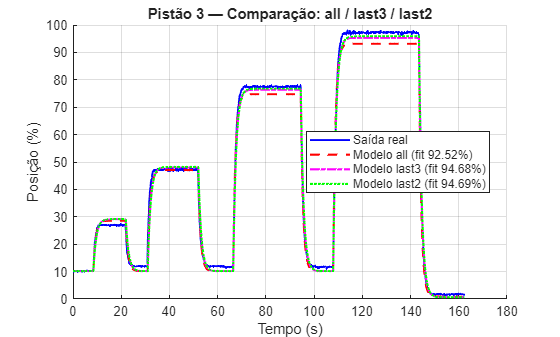

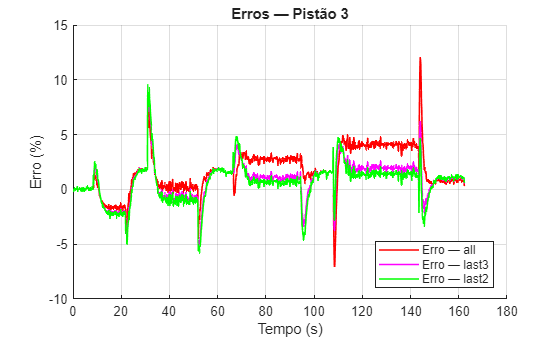

fits = show_fit_all_subsets(out, 1, 'Pistão 3');

disp(fits)   % ordem: [fit_all, fit_last3, fit_last2] (para os que existirem)

   92.5174
   94.6821
   94.6876



%--------Pisão 4--------%
Kp = 5;

ui = [10;10;10;10]; uf = [30;50;80;100];
yi = [10.01;11.84;11.57;11.6]; yf = [26.49;45.078;75.47;95.26];
t_i = [8.38;30.642;66.268;107.74];
t_tau_abs = [8.826;31.3055;67.1;108.892];
meas(4).tempo  = tempo(:);
meas(4).degrau = degrau(:);
meas(4).saida  = resposta4(:);
out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas);

% Acessando o modelo "last2"
T_last2 = out(1).models(strcmp({out(1).models.name},'last2')).T_avg


T_last2 =
 
    0.9212
  -----------
  0.992 s + 1
 
Continuous-time transfer function.


G_last2 = out(1).models(strcmp({out(1).models.name},'last2')).G_avg


G_last2 =
 
    0.1857
  -----------
  s + 0.07943
 
Continuous-time transfer function.


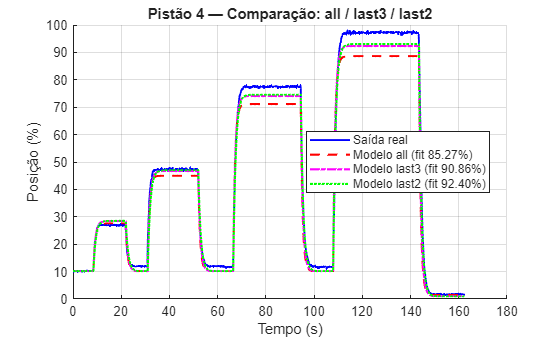

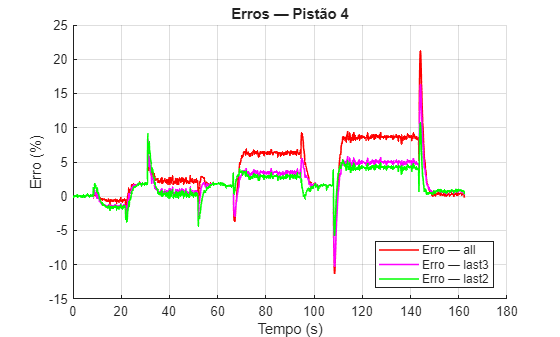

fits = show_fit_all_subsets(out, 1, 'Pistão 4');

disp(fits)   % ordem: [fit_all, fit_last3, fit_last2] (para os que existirem)

   85.2674
   90.8590
   92.3985



%--------Pisão 5--------%
Kp = 5;

ui = [10;10;10;10]; uf = [30;50;80;100];
yi = [10.164;12.33;13.1;13.06]; yf = [26.715;45.65;76.34;95.793];
t_i = [8.38;30.642;66.268;107.74];
t_tau_abs = [8.826;31.5425;67.23;108.956];
meas(5).tempo  = tempo(:);
meas(5).degrau = degrau(:);
meas(5).saida  = resposta5(:);
out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas);

% Acessando o modelo "last2"
T_last2 = out(1).models(strcmp({out(1).models.name},'last2')).T_avg


T_last2 =
 
    0.9113
  -----------
  1.089 s + 1
 
Continuous-time transfer function.


G_last2 = out(1).models(strcmp({out(1).models.name},'last2')).G_avg


G_last2 =
 
    0.1674
  -----------
  s + 0.08141
 
Continuous-time transfer function.


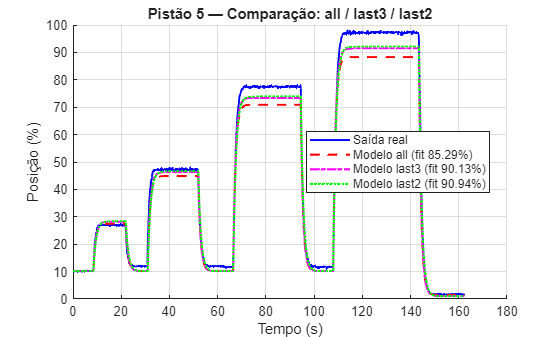

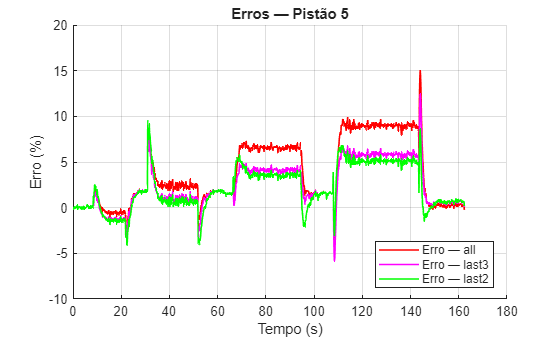

fits = show_fit_all_subsets(out, 1, 'Pistão 5');

disp(fits)   % ordem: [fit_all, fit_last3, fit_last2] (para os que existirem)

   85.2884
   90.1322
   90.9428



%--------Pisão 6--------%
Kp = 5;

ui = [10;10;10;10]; uf = [30;50;80;100];
yi = [10.17;11.92;11.89;11.75]; yf = [26.61;47.023;76.872;97.591];
t_i = [8.38;30.642;66.268;107.74];
t_tau_abs = [8.826;31.424;67.34;108.956];
meas(6).tempo  = tempo(:);
meas(6).degrau = degrau(:);
meas(6).saida  = resposta6(:);
out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas);

% Acessando o modelo "last2"
T_last2 = out(1).models(strcmp({out(1).models.name},'last2')).T_avg


T_last2 =
 
    0.9411
  -----------
  1.144 s + 1
 
Continuous-time transfer function.


G_last2 = out(1).models(strcmp({out(1).models.name},'last2')).G_avg


G_last2 =
 
    0.1645
  -----------
  s + 0.05153
 
Continuous-time transfer function.


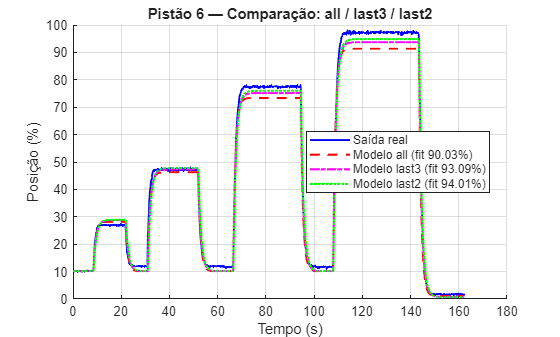

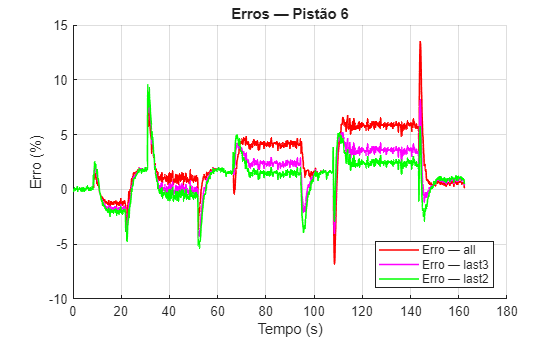

fits = show_fit_all_subsets(out, 1, 'Pistão 6');

disp(fits)   % ordem: [fit_all, fit_last3, fit_last2] (para os que existirem)

   90.0311
   93.0918
   94.0148



%--------System Identification--------%
T1 = tf(tfpistao1.Numerator, tfpistao1.Denominator);

%Como Kp = 1 e H(s) = 1 (realimentação unitária), G(s) = T / (1 - T)
G1 = minreal( T1 / (5*(1 - T1)) );

disp('Função de transferência do Pistão 1 - G(s) em malha aberta:');

Função de transferência do Pistão 1 - G(s) em malha aberta:


G1


G1 =
 
    1.394
  ----------
  s + 0.2136
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 2 =====
T2 = tf(tfpistao2.Numerator, tfpistao2.Denominator);
G2 = minreal( T2 / (5*(1 - T2)) );
disp('Função de transferência do Pistão 2 - G(s) em malha aberta:');

Função de transferência do Pistão 2 - G(s) em malha aberta:


G2


G2 =
 
    1.435
  ----------
  s + 0.1338
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 3 =====

T3 = tf(tfpistao3.Numerator, tfpistao3.Denominator);
G3 = minreal( T3 / (5*(1 - T3)) );
disp('Função de transferência do Pistão 3 - G(s) em malha aberta:');

Função de transferência do Pistão 3 - G(s) em malha aberta:


G3


G3 =
 
    1.365
  ----------
  s + 0.1754
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 4 =====
T4 = tf(tfpistao4.Numerator, tfpistao4.Denominator);
G4 = minreal( T4 / (5*(1 - T4)) );
disp('Função de transferência do Pistão 4 - G(s) em malha aberta:');

Função de transferência do Pistão 4 - G(s) em malha aberta:


G4


G4 =
 
    1.408
  ----------
  s + 0.3629
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 5 =====
T5 = tf(tfpistao5.Numerator, tfpistao5.Denominator);
G5 = minreal( T5 / (5*(1 - T5)) );
disp('Função de transferência do Pistão 5 - G(s) em malha aberta:');

Função de transferência do Pistão 5 - G(s) em malha aberta:


G5


G5 =
 
     1.32
  ----------
  s + 0.2937
 
Continuous-time transfer function.



% ===== Malha aberta Pistão 6 =====
T6 = tf(tfpistao6.Numerator, tfpistao6.Denominator);
G6 = minreal( T6 / (5*(1 - T6)) );
disp('Função de transferência do Pistão 6 - G(s) em malha aberta:');

Função de transferência do Pistão 6 - G(s) em malha aberta:


G6


G6 =
 
    1.387
  ----------
  s + 0.2199
 
Continuous-time transfer function.


C1c = tf([5 0.4], [1 0]);  % Kp, Ki, Kd


C1c =
 
  5 s + 0.4
  ---------
      s
 
Continuous-time transfer function.


controlSystemDesigner(G1, C1c);

C2c = tf([5 0.4], [1 0]);


C2c =
 
  5 s + 0.4
  ---------
      s
 
Continuous-time transfer function.


controlSystemDesigner(G2);

C3c = tf([5 0.4], [1 0]);
controlSystemDesigner(G3, C3c);

C4c = tf([5 0.4], [1 0]);
controlSystemDesigner(G4, C4c);

C5c = tf([5 0.4], [1 0]);
controlSystemDesigner(G5, C5c);

C6c = pid(5, 0.4, 0);  % Kp, Ki, Kd
controlSystemDesigner(G6, C6c);

C2 = tf([5 0.4],[1 0]);   % (5s+0.4)/s

Gs     = {G1, G3, G4, G5, G6};
labels = [1   3   4   5   6];

for k = 1:numel(Gs)
    Gi = Gs{k};
    fprintf('\n------ Pistão %d ------\n', labels(k));

    % SUA FUNÇÃO com 3 argumentos:
    [C, numC, denC] = controller_follow_G2(Gi, G2, C2);

    disp('C(s) obtido:');  C

    [Kp, Ki, r, a, Cpi] = pi_from_C(C);
    fprintf('a (em s+a) = %.6g | resto r = %.6g | PI: Kp = %.6g, Ki = %.6g\n', a, r, Kp, Ki);
end


------ Pistão 1 ------


C(s) obtido:

C =
 
  5.148 s^2 + 1.511 s + 0.08797
  -----------------------------
         s^2 + 0.1338 s
 
Continuous-time transfer function.


a (em s+a) = 0.133801 | resto r = -0.0221005 | PI: Kp = 5.14781, Ki = 0.822605



------ Pistão 3 ------


C(s) obtido:

C =
 
  5.255 s^2 + 1.342 s + 0.07374
  -----------------------------
         s^2 + 0.1338 s
 
Continuous-time transfer function.


a (em s+a) = 0.133801 | resto r = -0.0117632 | PI: Kp = 5.25517, Ki = 0.639055



------ Pistão 4 ------


C(s) obtido:

C =
 
  5.097 s^2 + 2.257 s + 0.148
  ---------------------------
        s^2 + 0.1338 s
 
Continuous-time transfer function.


a (em s+a) = 0.133801 | resto r = -0.0628122 | PI: Kp = 5.09688, Ki = 1.57524



------ Pistão 5 ------


C(s) obtido:

C =
 
  5.436 s^2 + 2.031 s + 0.1277
  ----------------------------
         s^2 + 0.1338 s
 
Continuous-time transfer function.


a (em s+a) = 0.133801 | resto r = -0.0467551 | PI: Kp = 5.43617, Ki = 1.30393



------ Pistão 6 ------


C(s) obtido:

C =
 
  5.172 s^2 + 1.551 s + 0.09101
  -----------------------------
         s^2 + 0.1338 s
 
Continuous-time transfer function.


a (em s+a) = 0.133801 | resto r = -0.023968 | PI: Kp = 5.1724, Ki = 0.859284



function [Kp, Ki, r, a, Cpi] = pi_from_C(C)
    C = minreal(tf(C));
    [num, den] = tfdata(C, 'v');
    den = den/den(1);   % normaliza: [1 a 0]
    a   = den(2);
    [q, rpoly] = deconv(num, [1 a]);   % N(s) / (s+a) = q(s) + r/(s+a)
    Kp = q(1);  Ki = q(2);
    r  = rpoly(end);
    Cpi = tf([Kp Ki],[1 0]);
end


function [C, numC, denC] = controller_follow_G2(G1, G2, C2)
%CONTROLLER_FOLLOW_G2  Calcula C para que a malha "siga" G2 (fórmula dada).
%   C = (G2*C2) / (G1*C1 + G2*C2 - G1*G2*C2)
%
%   Parâmetros:
%     G1, G2 : plantas (tf/zpk/ss, SISO)
%     C1, C2 : filtros/pesos (tf/zpk/ss). Se omitidos, usa 1.
%
%   Retornos:
%     C      : controlador (tf)
%     numC   : numerador de C como vetor
%     denC   : denominador de C como vetor
%
%   Obs:
%     - Usa minreal para cancelar fatores redundantes.
%     - Se C sair impróprio, considere adicionar um roll-off (ex.: 1/(1+s/wc)).

    % Fórmula direta
    C = minreal( (G2*C2) / ( G1 ) );

    % Polinômios (se for tf)
    try
        [numC, denC] = tfdata(C, 'v');
    catch
        % se C vier como zpk/ss, converte
        C = tf(C);
        [numC, denC] = tfdata(C, 'v');
    end
end


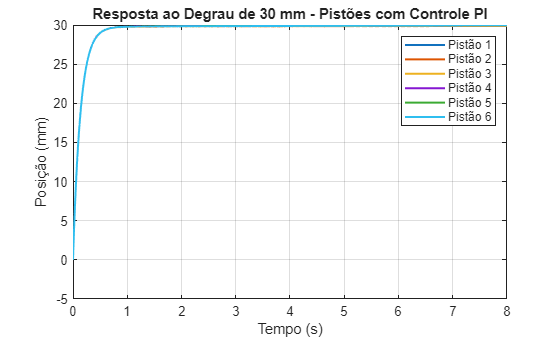

% === Controladores PID (ajuste os ganhos manualmente) ===
%C1 = pid(5.3375, 0.427, 0.0);
C1 = pid(5.1478, 0.8226, 0.0);
C2 = pid(5, 0.4, 0.0);
C3 = pid(5.25517, 0.639055, 0.0);
C4 = pid(5.09688, 1.57524, 0.0);
C5 = pid(5.43617, 1.30393, 0.0);
C6 = pid(5.1724, 0.859284, 0.0);

% === Malhas abertas (já extraídas com sucesso antes) ===
% G1, G2, ..., G6 já devem estar no workspace

% === Malhas fechadas ===
T1 = feedback(C1 * G1, 1);
T2 = feedback(C2 * G2, 1);
T3 = feedback(C3 * G3, 1);
T4 = feedback(C4 * G4, 1);
T5 = feedback(C5 * G5, 1);
T6 = feedback(C6 * G6, 1);

% === Gráfico comparativo ===
% === Tempo de simulação ===
t = 0:0.01:8;               % de 0 a 40 segundos, passo de 0.01s
u = 30 * ones(size(t));      % degrau de 30 mm

% === Respostas simuladas com entrada de 30 mm ===
y1 = lsim(T1, u, t);
y2 = lsim(T2, u, t);
y3 = lsim(T3, u, t);
y4 = lsim(T4, u, t);
y5 = lsim(T5, u, t);
y6 = lsim(T6, u, t);

% === Plot ===
figure;
plot(t, y1, t, y2, t, y3, t, y4, t, y5, t, y6, 'LineWidth', 1.5);
title('Resposta ao Degrau de 30 mm - Pistões com Controle PI');
legend('Pistão 1', 'Pistão 2', 'Pistão 3', 'Pistão 4', 'Pistão 5', 'Pistão 6');
ylabel('Posição (mm)');
xlabel('Tempo (s)');
grid on;

% === Controle PID sincronizado sem overshoot ===
% Objetivo: Resposta rápida, sem ultrapassagem e sincronizada entre pistões

% === Parâmetros de projeto ===
velocidade_resposta = 0.1;  % frequência desejada (rad/s)

% === Projeto dos controladores com pidtune ===
opts = pidtuneOptions('DesignFocus', 'reference-tracking', ...
                      'PhaseMargin', 45);

[C1, ~] = pidtune(G1, 'PI', velocidade_resposta, opts);
[C2, ~] = pidtune(G2, 'PI', velocidade_resposta, opts);
[C3, ~] = pidtune(G3, 'PI', velocidade_resposta, opts);
[C4, ~] = pidtune(G4, 'PI', velocidade_resposta, opts);
[C5, ~] = pidtune(G5, 'PI', velocidade_resposta, opts);
[C6, ~] = pidtune(G6, 'PI', velocidade_resposta, opts);

% === Mostrar os ganhos PID no console ===
controladores = {C1, C2, C3, C4, C5, C6};

fprintf('\n=== Ganhos PID ===\n');


=== Ganhos PID ===


for i = 1:6
    C = controladores{i};

    fprintf('Pistão %d:  Kp = %.4f   Ki = %.4f   Kd = %.4f\n', ...
            i, C.Kp, C.Ki, C.Kd);
end

Pistão 1:  Kp = 0.0000   Ki = 0.0169   Kd = 0.0000
Pistão 2:  Kp = 0.0000   Ki = 0.0116   Kd = 0.0000
Pistão 3:  Kp = 0.0000   Ki = 0.0148   Kd = 0.0000
Pistão 4:  Kp = 0.0000   Ki = 0.0267   Kd = 0.0000
Pistão 5:  Kp = 0.0000   Ki = 0.0235   Kd = 0.0000
Pistão 6:  Kp = 0.0000   Ki = 0.0174   Kd = 0.0000


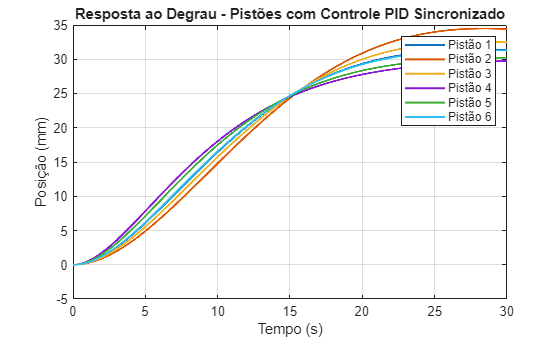


% === Malhas fechadas ===
T1 = feedback(C1 * G1, 1);
T2 = feedback(C2 * G2, 1);
T3 = feedback(C3 * G3, 1);
T4 = feedback(C4 * G4, 1);
T5 = feedback(C5 * G5, 1);
T6 = feedback(C6 * G6, 1);

% === Simulação com degrau de 30 mm ===
t = 0:0.01:30;
u = 30 * ones(size(t));

y1 = lsim(T1, u, t);
y2 = lsim(T2, u, t);
y3 = lsim(T3, u, t);
y4 = lsim(T4, u, t);
y5 = lsim(T5, u, t);
y6 = lsim(T6, u, t);

% === Gráfico comparativo ===
figure;
plot(t, y1, t, y2, t, y3, t, y4, t, y5, t, y6, 'LineWidth', 1.5);
title('Resposta ao Degrau - Pistões com Controle PID Sincronizado');
legend('Pistão 1', 'Pistão 2', 'Pistão 3', 'Pistão 4', 'Pistão 5', 'Pistão 6');
ylabel('Posição (mm)');
xlabel('Tempo (s)');
grid on;

function out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas)
% AVG_MODELS_FROM_STEPS
% Calcula modelos médios (1ª ordem) para cada pistão a partir de múltiplos degraus.
%
% Assinatura:
%   out = avg_models_from_steps(Kp, ui, uf, yi, yf, t_i, t_tau_abs, meas)
%
% Parâmetros
%   Kp         : escalar ou 1xP (ganho proporcional usado nos ensaios)
%   ui, uf     : N x P (entrada inicial/final por ensaio e pistão)
%   yi, yf     : N x P (saída inicial/final por ensaio e pistão)
%   t_i        : N x P (instante do degrau)
%   t_tau_abs  : N x P (instante absoluto em que atingiu 63,2%)
%   meas       : (OPCIONAL) struct com medição para validação por pistão:
%                  meas(p).tempo  : vetor tempo
%                  meas(p).degrau : vetor entrada
%                  meas(p).saida  : vetor saída
%                Se omitido, não calcula fit/simulações.
%
% Retorno (out é um array 1xP de structs):
%   out(p).perTrial.K_T, out(p).perTrial.tau_T, out(p).perTrial.validIdx
%   out(p).models(s) para s∈{1..3} (all, last3, last2):
%       .name        : 'all' | 'last3' | 'last2'
%       .K_T_med     : mediana do ganho de T
%       .tau_T_med   : mediana da constante de tempo de T
%       .T_avg       : tf de 1ª ordem em malha fechada
%       .G_avg       : tf de 1ª ordem em malha aberta (planta)
%       .fit         : (se meas fornecido) ajuste em %
%       .t, .y_hat   : (se meas) tempo reamostrado e resposta simulada
%       .y, .e       : (se meas) saída reamostrada e erro (y - y_hat)
%
% Requisitos:
%   Control System Toolbox (tf, feedback, lsim).
%
% Ex.: ver exemplos ao final do arquivo.

    arguments
        Kp {mustBeNonempty}
        ui double
        uf double
        yi double
        yf double
        t_i double
        t_tau_abs double
        meas struct = struct([])   % opcional
    end

    % --- Checagens rápidas de dimensão ---
    [N, P] = size(yi);
    assert(isequal(size(ui), [N P]) && isequal(size(uf), [N P]), 'ui/uf devem ser N x P');
    assert(isequal(size(yf), [N P]) && isequal(size(t_i), [N P]) && isequal(size(t_tau_abs), [N P]), ...
        'yf, t_i, t_tau_abs devem ser N x P');

    % Normaliza Kp
    if isscalar(Kp), Kp = repmat(Kp, 1, P); end
    assert(numel(Kp) == P, 'Kp deve ser escalar ou 1xP');

    % Subconjuntos a calcular
    subsetDefs = { 'all', Inf; 'last3', 3; 'last2', 2 };  % {nome, quantos_ultimos}
    nSubs = size(subsetDefs,1);

    out = repmat(struct(), 1, P);

    for p = 1:P
        % --- Por-ensaio ---
        du    = uf(:,p) - ui(:,p);
        dy    = yf(:,p) - yi(:,p);
        K_T   = dy ./ max(du, eps);                        % evita div/0
        tau_T = t_tau_abs(:,p) - t_i(:,p);

        % válidos
        valid = isfinite(K_T) & isfinite(tau_T) & (tau_T > 0) & (abs(du) > 0);
        validIdx = find(valid);

        out(p).perTrial.K_T     = K_T;
        out(p).perTrial.tau_T   = tau_T;
        out(p).perTrial.validIdx= validIdx;

        if isempty(validIdx)
            warning('Pistão %d: nenhum ensaio válido.', p);
        end

        % --- Para cada subconjunto: all / last3 / last2 ---
        models = struct([]);
        for s = 1:nSubs
            name   = subsetDefs{s,1};
            howMany= subsetDefs{s,2};

            idxUse = validIdx;
            if isfinite(howMany) && numel(idxUse) >= howMany
                idxUse = idxUse(end-howMany+1:end);
            elseif isfinite(howMany) && numel(idxUse) < howMany
                % se não há amostras suficientes, pula
                continue;
            end

            KTmed   = median(K_T(idxUse));
            TAUmed  = median(tau_T(idxUse));

            % Modelo em malha fechada (1ª ordem)
            T_avg = tf(KTmed, [TAUmed 1]);

            % Planta via T = (Kp*G)/(1+Kp*G) => G = T / (Kp*(1-T))
            G_avg = minreal( T_avg / (Kp(p) * (1 - T_avg)) );

            m = struct('name', name, ...
                       'K_T_med', KTmed, ...
                       'tau_T_med', TAUmed, ...
                       'T_avg', T_avg, ...
                       'G_avg', G_avg);

            % --- Validação opcional (se medições fornecidas) ---
            if ~isempty(meas) && numel(meas) >= p && ...
               isfield(meas(p),'tempo') && isfield(meas(p),'degrau') && isfield(meas(p),'saida') ...
               && ~isempty(meas(p).tempo)

                T_sim = feedback(Kp(p) * G_avg, 1);

                [t_uni, u_uni, y_uni] = uniformize_step(meas(p).tempo(:), meas(p).degrau(:), meas(p).saida(:));

                u0 = u_uni(1);
                y0 = y_uni(1);
                y_hat = lsim(T_sim, u_uni - u0, t_uni) + y0;

                fit = 100 * (1 - norm(y_uni - y_hat) / norm(y_uni - mean(y_uni)));

                m.fit = fit;
                m.t   = t_uni;
                m.y   = y_uni;
                m.y_hat = y_hat;
                m.e   = y_uni - y_hat;
            end

            models = [models; m]; %#ok<AGROW>
        end

        out(p).models = models;
    end
end

% ===== Helper: uniformiza tempo + reamostra =====
function [t_uni, u_uni, y_uni] = uniformize_step(t, u, y)
    % ordena e remove duplicados mantendo ordem
    [t, ia] = unique(t, 'stable');
    u = u(ia); y = y(ia);

    % passo típico
    dt = diff(t);
    Ts = median(dt(~isnan(dt) & isfinite(dt)));
    if ~isfinite(Ts) || Ts <= 0
        error('Não foi possível inferir Ts a partir do vetor de tempo.');
    end

    % grade uniforme
    t_uni = (t(1):Ts:t(end)).';

    % entrada tipo degrau preserva níveis (previous), saída linear
    u_uni = interp1(t, u, t_uni, 'previous', 'extrap');
    y_uni = interp1(t, y, t_uni, 'linear',   'extrap');
end


function [fit, hComp, hErr] = show_fit(out, p, subsetName, pistonLabel)
% SHOW_FIT - Plota comparação e erro para 1 pistão e 1 subset ('all'|'last3'|'last2')
% Retorna: fit (%) e handles das figuras.
%
% Uso:
%   [fit, h1, h2] = show_fit(out, 1, 'last2', 'Pistão 1');

    if nargin < 4 || isempty(pistonLabel), pistonLabel = sprintf('Pistão %d', p); end

    mnames = {out(p).models.name};
    k = find(strcmp(mnames, subsetName), 1);
    assert(~isempty(k), 'Subset "%s" não encontrado para o pistão %d.', subsetName, p);

    m = out(p).models(k);
    assert(isfield(m,'t') && ~isempty(m.t), ...
        'Sem medições associadas neste modelo. Passe "meas" na avg_models_from_steps.');

    fit = m.fit;

    % ----- Gráfico comparativo -----
    hComp = figure; grid on; hold on
    plot(m.t, m.y, 'b', 'LineWidth', 1.5)
    plot(m.t, m.y_hat, '--r', 'LineWidth', 1.8)
    xlabel('Tempo (s)'); ylabel('Posição (%)')
    legend('Saída real', sprintf('Modelo %s', subsetName), 'Location','best')
    title(sprintf('%s — %s | fit = %.2f %%', pistonLabel, subsetName, fit))

    % ----- Gráfico de erro -----
    hErr = figure; grid on
    plot(m.t, m.e, 'k', 'LineWidth', 1.2)
    xlabel('Tempo (s)'); ylabel('Erro (%)')
    title(sprintf('Erro — %s — %s', pistonLabel, subsetName))
end

function fits = show_fit_all_subsets(out, p, pistonLabel)
% SHOW_FIT_ALL_SUBSETS - Plota comparativo (3 modelos) + erros (3 curvas)
% e retorna vetor com [fit_all, fit_last3, fit_last2].
%
% Uso:
%   fits = show_fit_all_subsets(out, 1, 'Pistão 1');

    if nargin < 3 || isempty(pistonLabel), pistonLabel = sprintf('Pistão %d', p); end

    % pega modelos disponíveis
    mnames = {out(p).models.name};
    want = {'all','last3','last2'};
    have = ismember(want, mnames);
    assert(any(have), 'Nenhum subset disponível para o pistão %d.', p);

    % coleta structs dos que existem
    M = struct([]);
    for i = 1:numel(want)
        k = find(strcmp(mnames, want{i}), 1);
        if ~isempty(k)
            m = out(p).models(k);
            assert(isfield(m,'t') && ~isempty(m.t), ...
                'Sem medições associadas neste modelo. Passe "meas" na avg_models_from_steps.');
            M = [M; m]; %#ok<AGROW>
        end
    end

    % --- Comparativo
    h1 = figure; grid on; hold on
    plot(M(1).t, M(1).y, 'b', 'LineWidth', 1.4)  % saída real (t comum entre modelos)
    leg = {'Saída real'};
    styles = {'--r','-.m',':g'};
    for i = 1:numel(M)
        plot(M(i).t, M(i).y_hat, styles{i}, 'LineWidth', 1.6);
        leg{end+1} = sprintf('Modelo %s (fit %.2f%%)', M(i).name, M(i).fit); %#ok<AGROW>
    end
    xlabel('Tempo (s)'); ylabel('Posição (%)')
    legend(leg, 'Location','best')
    title(sprintf('%s — Comparação: all / last3 / last2', pistonLabel))

    % --- Erros
    h2 = figure; grid on; hold on
    colors = {'r','m','g'};
    for i = 1:numel(M)
        plot(M(i).t, M(i).e, colors{i}, 'LineWidth', 1.2);
    end
    xlabel('Tempo (s)'); ylabel('Erro (%)')
    legend(arrayfun(@(m) sprintf('Erro — %s', m.name), M, 'UniformOutput', false), 'Location','best')
    title(sprintf('Erros — %s', pistonLabel))

    fits = arrayfun(@(m) m.fit, M);

    % se quiser retornar também os handles:
    % fits.handles = struct('comparativo', h1, 'erro', h2);
end

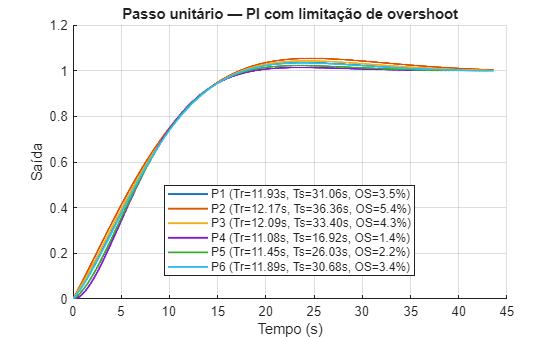

=== Métricas finais ===
    Pistao     Tr_s      Ts_s     Overshoot_pct       Kp          Ki   
    ______    ______    ______    _____________    ________    ________

      1       11.926    31.056        3.498        0.036043     0.02312
      2       12.172    36.358       5.3813        0.054029      0.0156
      3       12.094    33.399       4.2822        0.046363    0.020153
      4       11.076    16.921       1.3794               0    0.035965
      5       11.447    26.031       2.2345        0.017312    0.031895
      6       11.891    30.685       3.3824        0.034654    0.023793



G = {G1,G2,G3,G4,G5,G6};
result = tunePI_equal_times(G, Tr_alvo, Ts_alvo, 0);  % OS_max=5%

[C1,C2,C3,C4,C5,C6] = deal(result.controllers{:});




function result = tunePI_equal_times(G, Tr_target, Ts_target, OS_max)
if nargin < 4 || isempty(OS_max), OS_max = 5; end
n = numel(G); C = cell(1,n); Tcl = cell(1,n);
met = repmat(struct('Tr',NaN,'Ts',NaN,'OS',NaN,'Kp',NaN,'Ki',NaN),1,n);

% Heurística de banda inicial
w_tr = 2.2 / max(Tr_target, eps);
w_ts = 4.0 / max(Ts_target, eps);
w0   = sqrt(w_tr * w_ts);
wmin = max(1e-2, 0.2*w0);  wmax = 3*w0;     % <-- menos agressivo

% pidtune mais conservador
opts = pidtuneOptions('DesignFocus','reference-tracking','PhaseMargin',70); % <-- 70°

% pesos do custo
wTr=1.0; wTs=1.0; wOS=6.0;   % <-- pesa forte overshoot

for i = 1:n
    Gi = G{i};
    costfun = @(w) local_cost_PI(Gi,w,opts,Tr_target,Ts_target,OS_max,wTr,wTs,wOS);
    % busca fina
    try
        wi = fminbnd(costfun, wmin, wmax);
    catch
        gridw = logspace(log10(wmin), log10(wmax), 15);
        J = arrayfun(costfun, gridw); [~,kbest] = min(J); wi = gridw(kbest);
    end

    % "freio de mão" se ainda tiver overshoot
    for dec = 1:6
        Ctry = pidtune(Gi,'PI',wi,opts);  Ttry = feedback(Ctry*Gi,1);
        info = stepinfo(Ttry);
        if info.Overshoot <= OS_max || ~isfinite(info.Overshoot)
            break
        end
        wi = wi/1.6;  % reduz banda e tenta de novo
    end

    C{i}   = Ctry;
    Tcl{i} = Ttry;
    met(i).Tr = info.RiseTime;  met(i).Ts = info.SettlingTime;  met(i).OS = info.Overshoot;
    met(i).Kp = Ctry.Kp;        met(i).Ki = Ctry.Ki;
end

% Gráfico comparativo final
Ts_vec = [met.Ts]; Ts_vec = Ts_vec(isfinite(Ts_vec) & Ts_vec>0);
if isempty(Ts_vec)
    Tfinal = 10;                     % fallback (segundos)
else
    Tfinal = 1.2 * max(Ts_vec);      % 20% a mais que o pior Ts
end
t = linspace(0,Tfinal,2000); u = ones(size(t));
figure('Name','PI Equalizado - Comparativo'); grid on; hold on
leg = cell(1,n);
for i=1:n, plot(t, lsim(Tcl{i},u,t), 'LineWidth',1.4); leg{i}=sprintf('P%d (Tr=%.2fs, Ts=%.2fs, OS=%.1f%%)',i,met(i).Tr,met(i).Ts,met(i).OS); end
xlabel('Tempo (s)'); ylabel('Saída'); title('Passo unitário — PI com limitação de overshoot'); legend(leg,'Location','best')

Metrics = table((1:n)',[met.Tr]',[met.Ts]',[met.OS]',[met.Kp]',[met.Ki]', ...
    'VariableNames',{'Pistao','Tr_s','Ts_s','Overshoot_pct','Kp','Ki'});
disp('=== Métricas finais ==='); disp(Metrics);

result.controllers=C; result.modelsCL=Tcl; result.metrics=Metrics;
end

function J = local_cost_PI(G,w,opts,Tr_t,Ts_t,OS_max,wTr,wTs,wOS)
try
    C = pidtune(G,'PI',w,opts);
    T = feedback(C*G,1);
    info = stepinfo(T);
    Tr=info.RiseTime; Ts=info.SettlingTime; OS=info.Overshoot;
    J = wTr*(Tr-Tr_t)^2 + wTs*(Ts-Ts_t)^2 + wOS*max(0,OS-OS_max)^2;
    if ~isfinite(J), J=1e6; end
catch, J=1e6;
end
end

openExample('simulink_industrial/AntiWindupControlUsingAPIDControllerExample')